Sinusoide

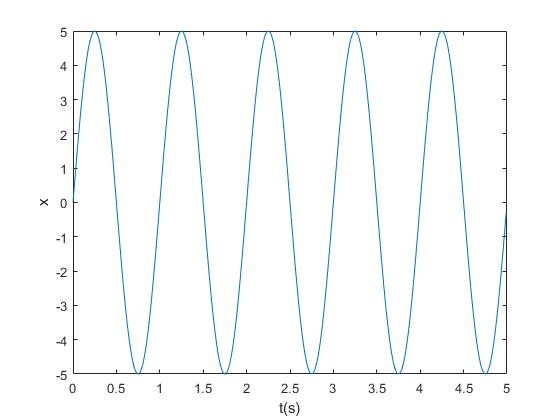

T = 1;      % periodo
f = 1/T;    %freq
A = 5;      % amplitude
valMedio = 0;
N = 100;    % n de amostras num periodo
Np = 5;     % n de periodos
Ta = T/N;
ti = (0:N-1)*Ta; 
xi = A*sin(2*pi*f*ti) + valMedio;
t = (0:(N*Np)-1)*Ta;
x = repmat(xi,1,Np); % o sinal
plot(t,x)
xlabel('t(s)');
ylabel('x');

Onda Quadrada (a começar na A)

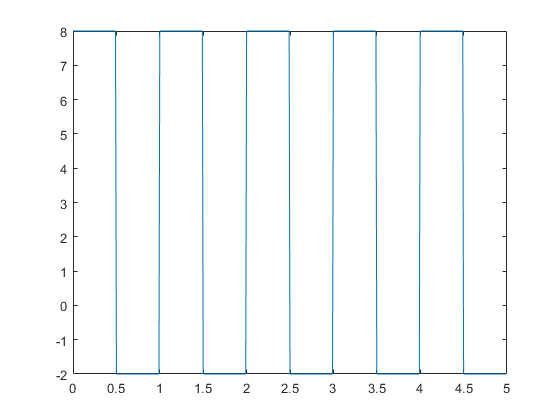

%f = 0; T = 1/f;
T = 1; 
f = 1/T; 
A = 5; 
valMedio = 3;
N = 100; % n de amostras num periodo
Np = 5;  % n de periodos
Ta = T/N;
ti = (0:N-1)*Ta; 
if rem(N,2) == 0 % N de amostras par
    xi = [2*A.*ones(1,N/2) zeros(1,N/2)] + (valMedio-2*A*0.5);
else % don't do this
    xi = [ones(1,round(N/2)) zeros(1,round(N/2)-1)];
end
t = (0:(N*Np)-1)*Ta;
x = repmat(xi,1,Np); 
plot(t,x)

Onda Triangular (a começar em 0)

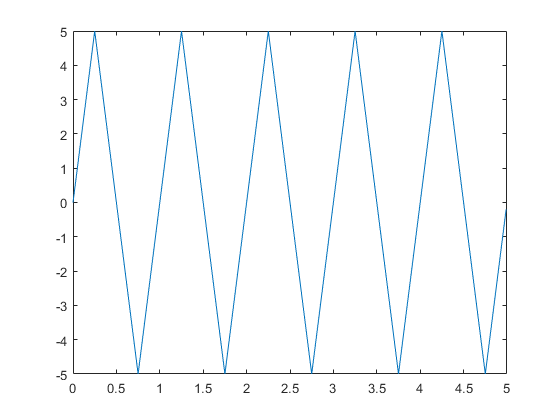

T = 1; 
f = 1/T; 
A = 5; 
valMedio = 0;
N = 100; % n de amostras num periodo
Np = 5; % n de periodos
Ta = T/N;
ti = (0:N-1)*Ta; 
xi = A*sawtooth(2*pi*f*ti+pi/2,1/2) + valMedio;
t = (0:(N*Np)-1)*Ta;
x = repmat(xi,1,Np); 
plot(t,x)

Onda Triangular (a começar na -A)

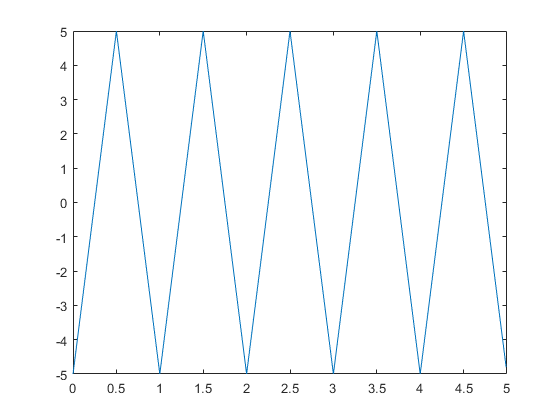

T = 1; 
f = 1/T;
A = 5; 
valMedio = 0;
N = 100; % n de amostras num periodo
Np = 5; % n de periodos
Ta = T/N;
ti = (0:N-1)*Ta; 
xi = A*sawtooth(2*pi*f*ti,1/2) + valMedio;
t = (0:(N*Np)-1)*Ta;
x = repmat(xi,1,Np); 
plot(t,x)

Onda em Serra

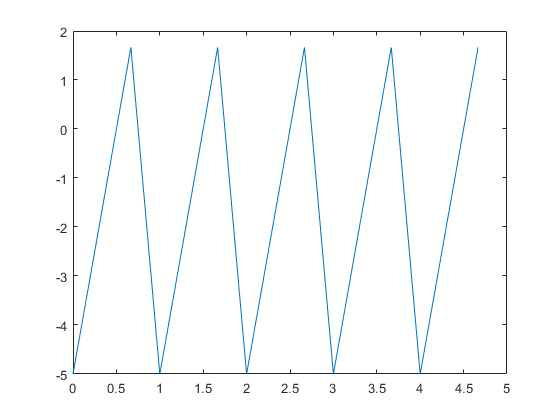

T = 1;
f = 1/T; 
A = 5; 
valMedio = 0;
N = 3; % n de amostras num periodo
Np = 5; % n de periodos
Ta = T/N;
ti = (0:N-1)*Ta; 
xi = A*sawtooth(2*pi*f*ti) + valMedio;
t = (0:(N*Np)-1)*Ta;
x = repmat(xi,1,Np); 
plot(t,x)

Funções

function [T,f] = periodoResultante(x) % x é um vetor de periodos
    T = lcm(sym(x));
    f = 1/T;
end

function [f,T] = freqResultante(x) % x é um vetor de freq
    f = gcd(sym(x));
    T = 1/f;
end

function potencia = potencia(x,T,Ta)
    t = 0:Ta:(T-Ta);
    s = 0;
    for k = 1:length(t)
        s = s + (x(k))^2;
    end
    potencia = s/length(t);
end

function x = transformFourier(Ta,f0,Np,ak,bk) % transforma coef de fourier em sinal
    T0 = 1/f0;
    n = T0/Ta;
    N = Np*n;
    t = (0:N-1)*Ta;
    x = zeros(1,N);
    for k = 1:length(ak)
        x = x + ak(k)*cos(k*2*pi*f0*t);
    end
    for k = 1:length(bk)
        x = x + bk(k)*sin(k*2*pi*f0*t);
    end
    if nargout == 0
        if N <= 10000
          plot(t,x,'o-','linewidth',2);
        end
    end
end

function [ak, bk] = invFourier(Ta,T0,x,K) % retira os coef de fourier do sinal
    f0 = 1/T0;
    t = 0:Ta:T0-Ta;
    y = x(1:length(t));
    ak = zeros(1,K);
    bk = zeros(1,K);
    for k = 1:K
        ak(k) = 2*f0*sum(y.*cos(2*pi*f0*k*t))*Ta;
        bk(k) = 2*f0*sum(y.*sin(2*pi*f0*k*t))*Ta;
    end
end

function [X,f] = espetro(x,Ta,w)
    N = length(x); 
    fa = 1/Ta; 
    if w ~= 0
        x = blackman(N)'.*x; 
    end
    X = fft(x)/length(x);
    f = (0:N-1)*fa/N; % freq max e min = 1/2 N de amostras p periodo
    f = fftshift(f); 
    X = fftshift(X); 
    i = find(f >= 0.5*fa); 
    f(i) = f(i) - fa;
    
    if nargout == 0
        stem(f,abs(X));
    end
end

function x = reconstroi(X) % reconstroi a partir do espetro
    X = fftshift(X);
    x = real(ifft(X));
end

function [y,yTa] = reconstroiSinal(x,Ta) % reconstroi a partir de amostras do sinal
    % fator de "oversampling"
    oversampling = 100;
    
    % instantes de tempo das amostras de x
    xT = (0:length(x)-1)*Ta;
    
    % cálculo de yTa (período de amostragem de y)
    yTa = Ta/oversampling;
    
    % instantes de tempo das amostras de y (tempos considerando 5 amostras extras de x de cada lado)
    yT = (-5*oversampling:oversampling*(length(x)+4))*yTa; % porque vai de -5 a 4???
    
    % inicialização do sinal de saída
    y = zeros(1,length(yT));
    
    % adição da contribuição de cada amostra de x no sinal y; cada amostra vem multiplicada pela funcão sinc centrada nessa amostra
    for ix=1:length(x)
      y = y+x(ix)*sinc((yT-xT(ix))/Ta); % passamos á função sinc o fa*T centrado na respetiva amostra do x.
    end
    
    % mostrar resultado quando não se usam os argumentos de saída desta função
    if nargout == 0
      figure; % nova figura
      plot(yT,y,'b',xT,x,'o');
      xlabel('time');
      ylabel('amplitude');
      title('Reconstrução do sinal x entre as suas amostras conhecidas');
      legend('x','reconstrução');
      zoom on;
      grid on;
    end
end